% Desired signal
N = 1000;
n = linspace(0,N-1,N);
ws = pi/6;
s = cos(ws*n);

% Added noise
noise = wgn(1,N,-60);
sn = s + noise;

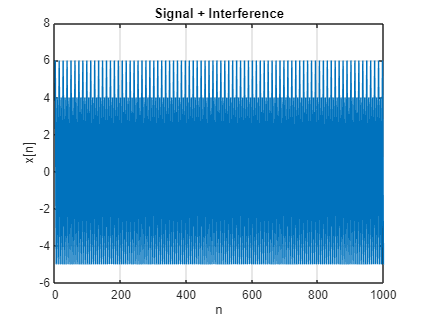

% Interference signal
w0 = pi/3;
i = 5*cos(w0*n);
x = sn + i;
figure
plot(x)
xlabel('n')
ylabel('x[n]')
title('Signal + Interference')
grid on

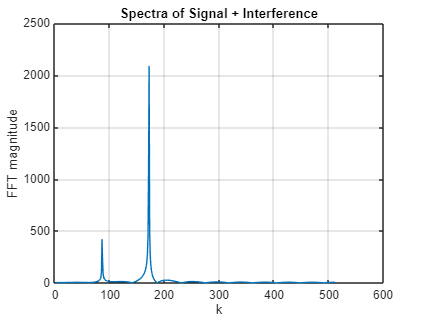

sifft = fft(x,1024);
sifft = sifft(1:end/2);

figure
plot(abs(sifft))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Signal + Interference')
grid on

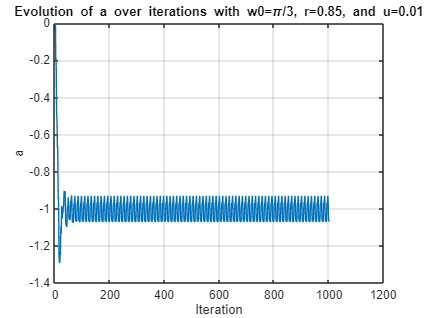

% First attempt
r = 0.85;
u = 0.01;

a = zeros(1,N);
y = zeros(1,N);

for i=1:N
    if i==1
        e = x(i);
        y(i) = e;
        a(i+1) = a(i);
    elseif i==2
        e = x(i) + a(i)*x(i-1);
        y(i) = e - r*a(i)*y(i-1);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    else
        e = x(i) + a(i)*x(i-1) + x(i-2);
        y(i) = e - r*a(i)*y(i-1) - r^2*y(i-2);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    end
    if abs(a(i+1)) > 2
        a(i+1) = 0;
    end
end

num = [1 a(end) 1];
den = [1 r*a(end) r^2];

figure
plot(a)
xlabel('Iteration')
ylabel('a')
title('Evolution of a over iterations with w0=\pi/3, r=0.85, and u=0.01')
grid on

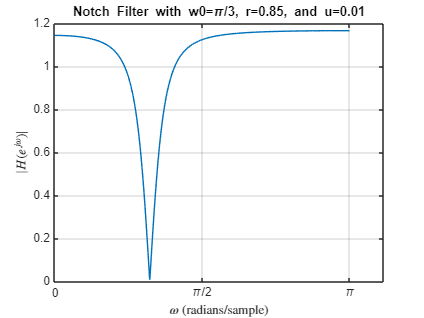


[H,w] = freqz(num,den,1024);
figure
plot(w,(abs(H)))
xlabel('$\omega$ (radians/sample)','Interpreter','latex')
ylabel('$|H(e^{j\omega})|$','Interpreter','latex')
title('Notch Filter with w0=\pi/3, r=0.85, and u=0.01')
xticks([0 pi/2 pi])
xticklabels({'0', '\pi/2', '\pi'})
grid on

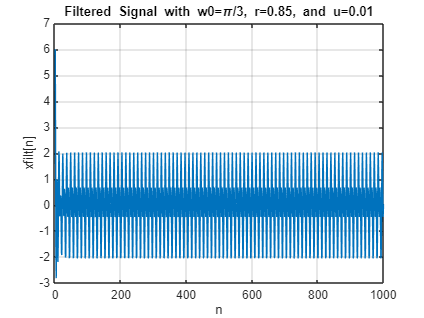


xfilt = filter(num,den,x);
figure
plot(xfilt)
xlabel('n')
ylabel('xfilt[n]')
title('Filtered Signal with w0=\pi/3, r=0.85, and u=0.01')
grid on

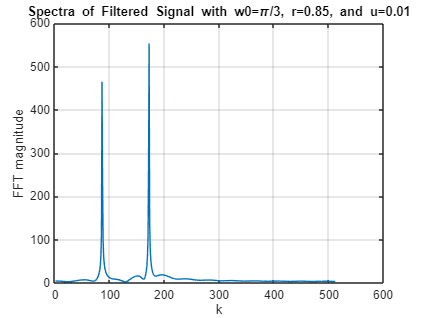


xfiltfft = fft(xfilt,1024);
figure
plot(abs(xfiltfft(1:end/2)))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Filtered Signal with w0=\pi/3, r=0.85, and u=0.01')
grid on

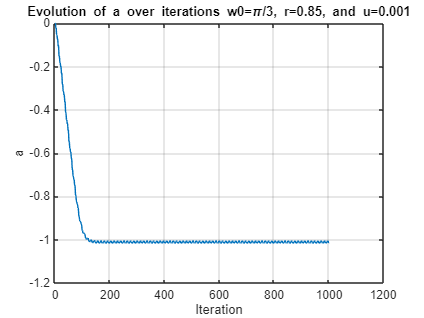

% Second attempt: best results
r = 0.85;
u = 0.001;

a = zeros(1,N);
y = zeros(1,N);

for i=1:N
    if i==1
        e = x(i);
        y(i) = e;
        a(i+1) = a(i);
    elseif i==2
        e = x(i) + a(i)*x(i-1);
        y(i) = e - r*a(i)*y(i-1);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    else
        e = x(i) + a(i)*x(i-1) + x(i-2);
        y(i) = e - r*a(i)*y(i-1) - r^2*y(i-2);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    end
    if abs(a(i+1)) > 2
        a(i+1) = 0;
    end
end

num = [1 a(end) 1];
den = [1 r*a(end) r^2];

figure
plot(a)
xlabel('Iteration')
ylabel('a')
title('Evolution of a over iterations w0=\pi/3, r=0.85, and u=0.001')
grid on

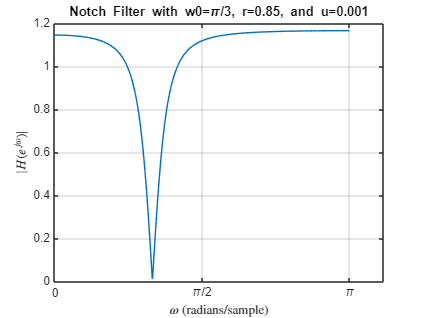


[H,w] = freqz(num,den,1024);
figure
plot(w,(abs(H)))
xlabel('$\omega$ (radians/sample)','Interpreter','latex')
ylabel('$|H(e^{j\omega})|$','Interpreter','latex')
title('Notch Filter with w0=\pi/3, r=0.85, and u=0.001')
xticks([0 pi/2 pi])
xticklabels({'0', '\pi/2', '\pi'})
grid on

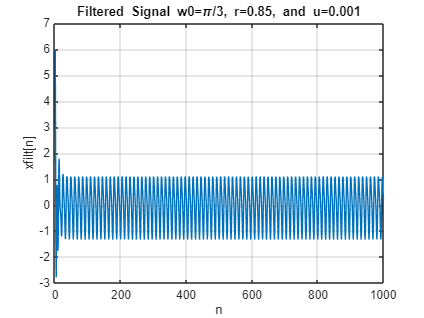


xfilt = filter(num,den,x);
figure
plot(xfilt)
xlabel('n')
ylabel('xfilt[n]')
title('Filtered Signal w0=\pi/3, r=0.85, and u=0.001')
grid on

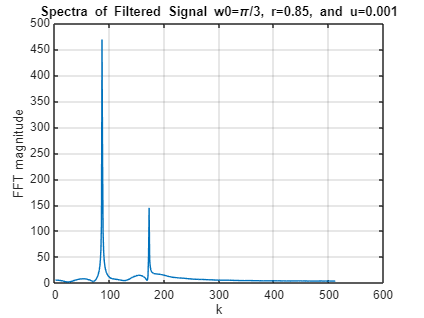


xfiltfft = fft(xfilt,1024);
figure
plot(abs(xfiltfft(1:end/2)))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Filtered Signal w0=\pi/3, r=0.85, and u=0.001')
grid on

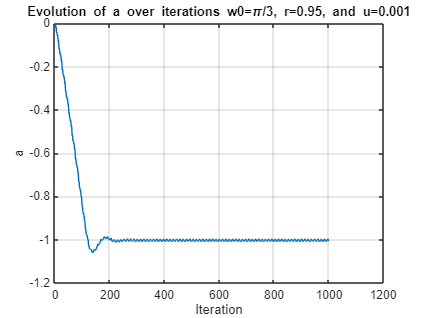

% Third attempt
r = 0.95;
u = 0.001;

a = zeros(1,N);
y = zeros(1,N);

for i=1:N
    if i==1
        e = x(i);
        y(i) = e;
        a(i+1) = a(i);
    elseif i==2
        e = x(i) + a(i)*x(i-1);
        y(i) = e - r*a(i)*y(i-1);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    else
        e = x(i) + a(i)*x(i-1) + x(i-2);
        y(i) = e - r*a(i)*y(i-1) - r^2*y(i-2);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    end
    if abs(a(i+1)) > 2
        a(i+1) = 0;
    end
end

num = [1 a(end) 1];
den = [1 r*a(end) r^2];

figure
plot(a)
xlabel('Iteration')
ylabel('a')
title('Evolution of a over iterations w0=\pi/3, r=0.95, and u=0.001')
grid on

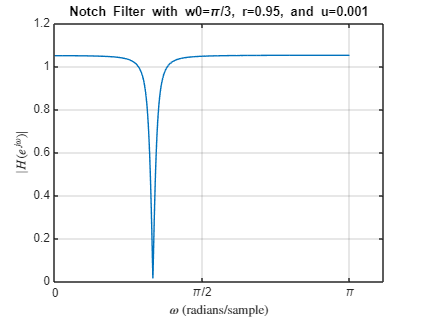


[H,w] = freqz(num,den,1024);
figure
plot(w,(abs(H)))
xlabel('$\omega$ (radians/sample)','Interpreter','latex')
ylabel('$|H(e^{j\omega})|$','Interpreter','latex')
title('Notch Filter with w0=\pi/3, r=0.95, and u=0.001')
xticks([0 pi/2 pi])
xticklabels({'0', '\pi/2', '\pi'})
grid on

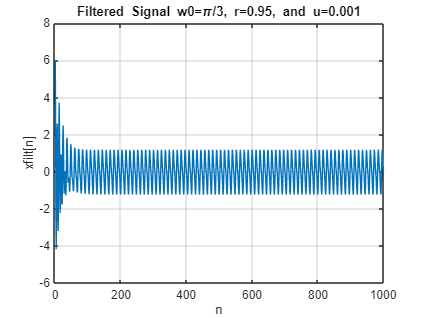


xfilt = filter(num,den,x);
figure
plot(xfilt)
xlabel('n')
ylabel('xfilt[n]')
title('Filtered Signal w0=\pi/3, r=0.95, and u=0.001')
grid on

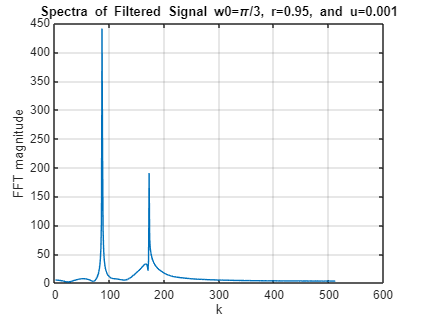


xfiltfft = fft(xfilt,1024);
figure
plot(abs(xfiltfft(1:end/2)))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Filtered Signal w0=\pi/3, r=0.95, and u=0.001')
grid on

% New desired signal
N = 1000;
n = linspace(0,N-1,N);
ws = pi/6;
s = cos(ws*n);

% Added noise
noise = wgn(1,N,-60);
sn = s + noise;

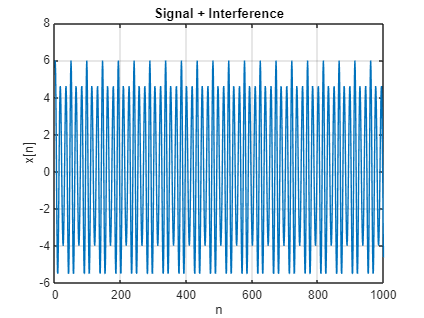

% Interference signal
w0 = pi/8;
i = 5*cos(w0*n);
x = sn + i;
figure
plot(x)
xlabel('n')
ylabel('x[n]')
title('Signal + Interference')
grid on

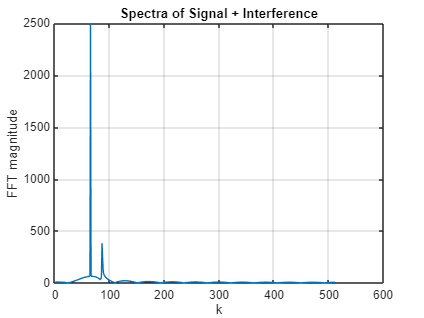

sifft = fft(x,1024);
sifft = sifft(1:end/2);

figure
plot(abs(sifft))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Signal + Interference')
grid on

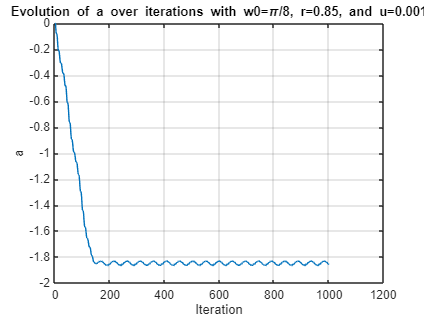

% Fourth attempt with closer interfering frequency
r = 0.85;
u = 0.001;

a = zeros(1,N);
y = zeros(1,N);

for i=1:N
    if i==1
        e = x(i);
        y(i) = e;
        a(i+1) = a(i);
    elseif i==2
        e = x(i) + a(i)*x(i-1);
        y(i) = e - r*a(i)*y(i-1);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    else
        e = x(i) + a(i)*x(i-1) + x(i-2);
        y(i) = e - r*a(i)*y(i-1) - r^2*y(i-2);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    end
    if abs(a(i+1)) > 2
        a(i+1) = 0;
    end
end

num = [1 a(end) 1];
den = [1 r*a(end) r^2];

figure
plot(a)
xlabel('Iteration')
ylabel('a')
title('Evolution of a over iterations with w0=\pi/8, r=0.85, and u=0.001')
grid on

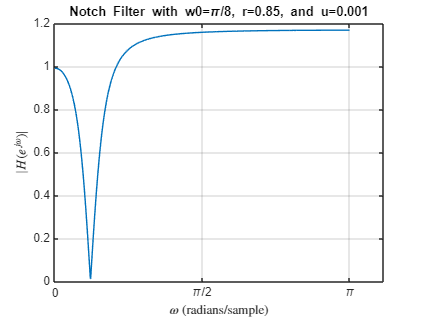


[H,w] = freqz(num,den,1024);
figure
plot(w,(abs(H)))
xlabel('$\omega$ (radians/sample)','Interpreter','latex')
ylabel('$|H(e^{j\omega})|$','Interpreter','latex')
title('Notch Filter with w0=\pi/8, r=0.85, and u=0.001')
xticks([0 pi/2 pi])
xticklabels({'0', '\pi/2', '\pi'})
grid on

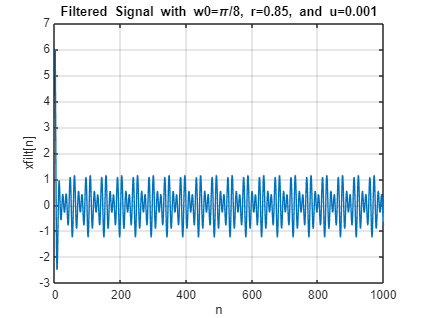


xfilt = filter(num,den,x);
figure
plot(xfilt)
xlabel('n')
ylabel('xfilt[n]')
title('Filtered Signal with w0=\pi/8, r=0.85, and u=0.001')
grid on

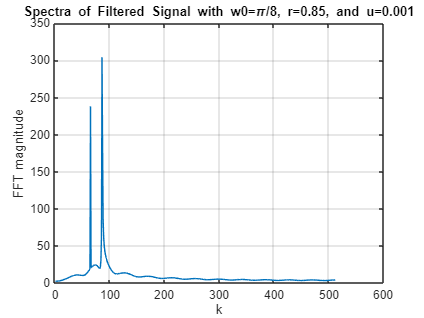


xfiltfft = fft(xfilt,1024);
figure
plot(abs(xfiltfft(1:end/2)))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Filtered Signal with w0=\pi/8, r=0.85, and u=0.001')
grid on

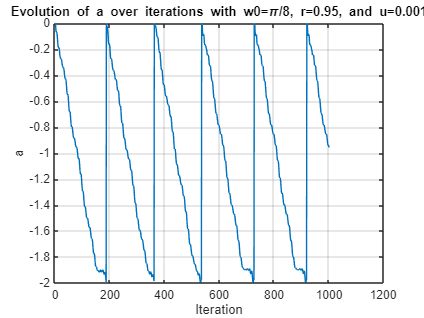

% Fifth attempt with closer interfering frequency
r = 0.95;
u = 0.001;

a = zeros(1,N);
y = zeros(1,N);

for i=1:N
    if i==1
        e = x(i);
        y(i) = e;
        a(i+1) = a(i);
    elseif i==2
        e = x(i) + a(i)*x(i-1);
        y(i) = e - r*a(i)*y(i-1);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    else
        e = x(i) + a(i)*x(i-1) + x(i-2);
        y(i) = e - r*a(i)*y(i-1) - r^2*y(i-2);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    end
    if abs(a(i+1)) > 2
        a(i+1) = 0;
    end
end

num = [1 a(end) 1];
den = [1 r*a(end) r^2];

figure
plot(a)
xlabel('Iteration')
ylabel('a')
title('Evolution of a over iterations with w0=\pi/8, r=0.95, and u=0.001')
grid on

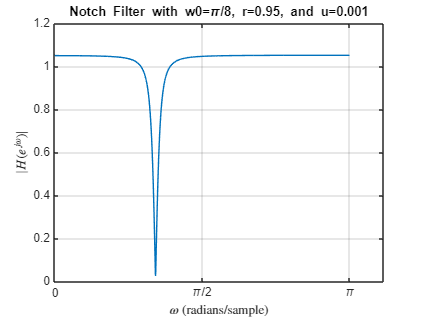


[H,w] = freqz(num,den,1024);
figure
plot(w,(abs(H)))
xlabel('$\omega$ (radians/sample)','Interpreter','latex')
ylabel('$|H(e^{j\omega})|$','Interpreter','latex')
title('Notch Filter with w0=\pi/8, r=0.95, and u=0.001')
xticks([0 pi/2 pi])
xticklabels({'0', '\pi/2', '\pi'})
grid on

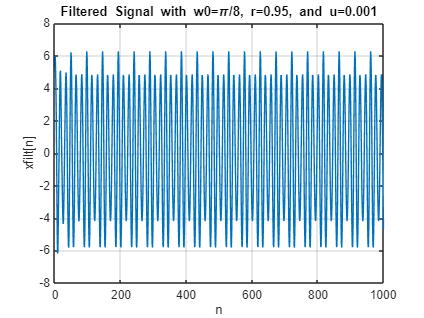


xfilt = filter(num,den,x);
figure
plot(xfilt)
xlabel('n')
ylabel('xfilt[n]')
title('Filtered Signal with w0=\pi/8, r=0.95, and u=0.001')
grid on

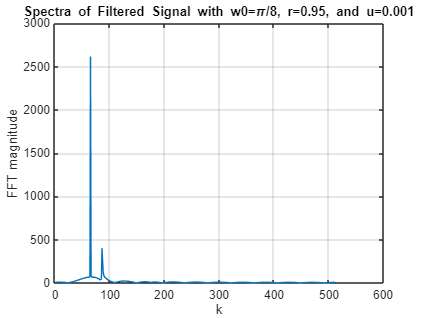


xfiltfft = fft(xfilt,1024);
figure
plot(abs(xfiltfft(1:end/2)))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Filtered Signal with w0=\pi/8, r=0.95, and u=0.001')
grid on

% New desired signal: higher power
N = 1000;
n = linspace(0,N-1,N);
ws = pi/6;
s = 5*cos(ws*n);

% Added noise
noise = wgn(1,N,-60);
sn = s + noise;

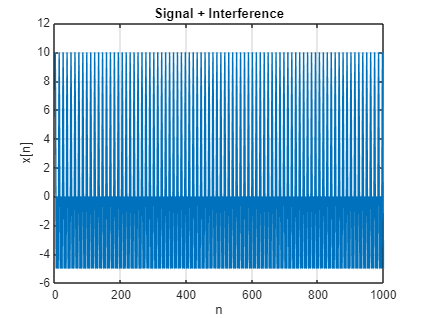

% Interference signal
w0 = pi/3;
i = 5*cos(w0*n);
x = sn + i;
figure
plot(x)
xlabel('n')
ylabel('x[n]')
title('Signal + Interference')
grid on

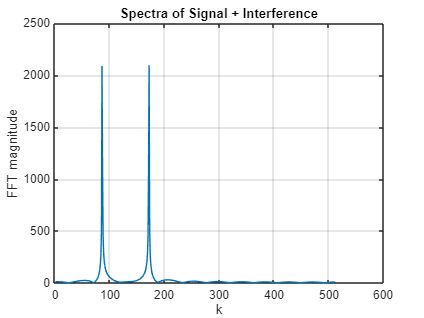

sifft = fft(x,1024);
sifft = sifft(1:end/2);

figure
plot(abs(sifft))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Signal + Interference')
grid on

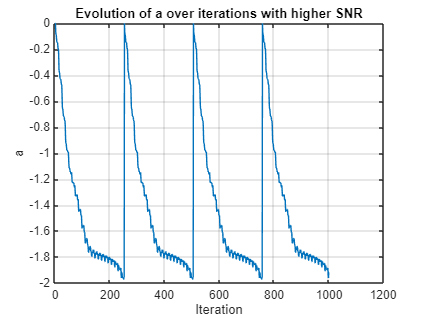

% Sixth attempt with higher signal power
r = 0.85;
u = 0.001;

a = zeros(1,N);
y = zeros(1,N);

for i=1:N
    if i==1
        e = x(i);
        y(i) = e;
        a(i+1) = a(i);
    elseif i==2
        e = x(i) + a(i)*x(i-1);
        y(i) = e - r*a(i)*y(i-1);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    else
        e = x(i) + a(i)*x(i-1) + x(i-2);
        y(i) = e - r*a(i)*y(i-1) - r^2*y(i-2);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    end
    if abs(a(i+1)) > 2
        a(i+1) = 0;
    end
end

num = [1 a(end) 1];
den = [1 r*a(end) r^2];

figure
plot(a)
xlabel('Iteration')
ylabel('a')
title('Evolution of a over iterations with higher SNR')
grid on

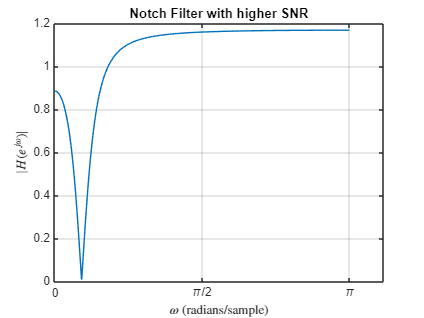


[H,w] = freqz(num,den,1024);
figure
plot(w,(abs(H)))
xlabel('$\omega$ (radians/sample)','Interpreter','latex')
ylabel('$|H(e^{j\omega})|$','Interpreter','latex')
title('Notch Filter with higher SNR')
xticks([0 pi/2 pi])
xticklabels({'0', '\pi/2', '\pi'})
grid on

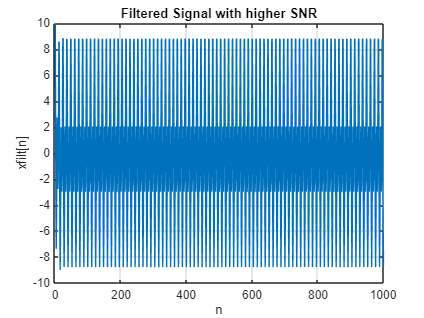


xfilt = filter(num,den,x);
figure
plot(xfilt)
xlabel('n')
ylabel('xfilt[n]')
title('Filtered Signal with higher SNR')
grid on

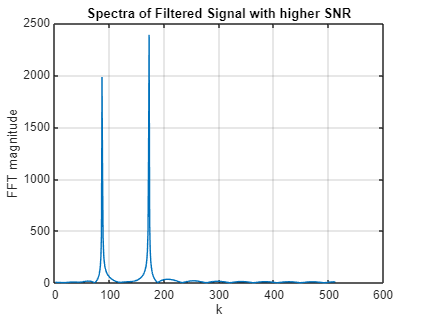

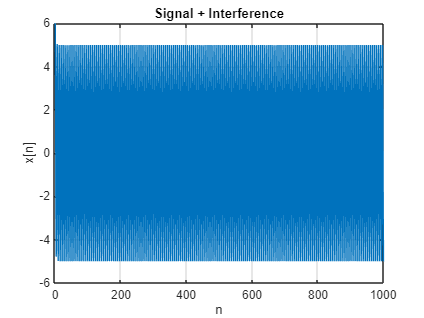

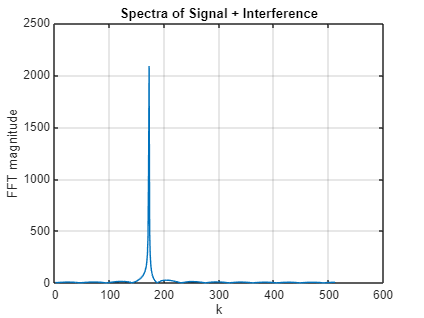

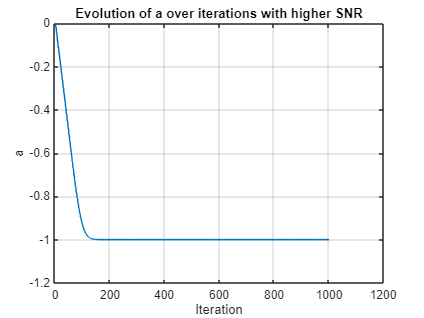

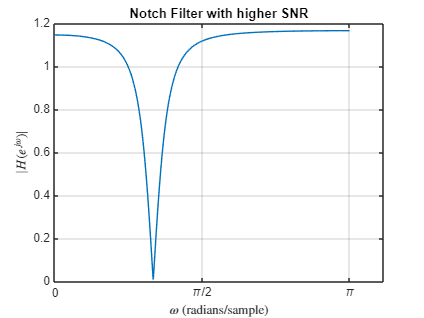

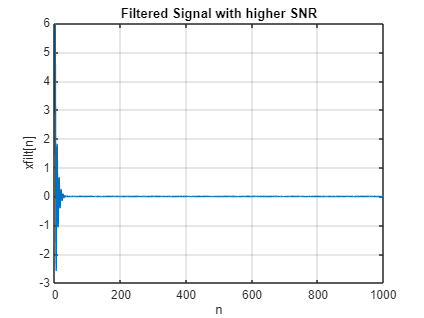

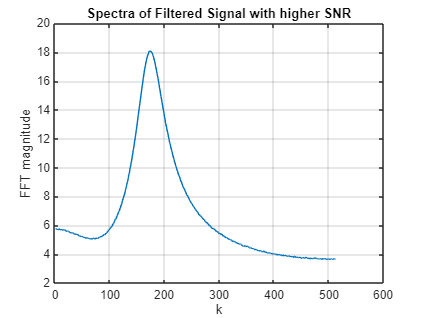


xfiltfft = fft(xfilt,1024);
figure
plot(abs(xfiltfft(1:end/2)))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Filtered Signal with higher SNR')
grid on